# Gabriel Colangelo

clear
close all
clc

## Problem 3a)


$$\underline{Find}: p,b,IP,(t-t_p),r_p,r_a$$


% Orbit constants
mu_earth    = 398600.4415;  % [km^3/s^2] 
R_earth     =  6378.1363; 

% Current orbit parameters
e_current   = 0.4;
a_current   = 4*R_earth; 
ta_current  = 225;          % Current true anomaly [deg]

% Manuever Parameters
ta_manuever = 120;          % True anomaly at manuever [deg]
deltaV      = 1.0;          % Delta V magnitude [km/s]
alpha       = -90;          % [deg]

% Semi-latus rectum
p_current   =  a_current*(1 - e_current^2);
fprintf('The current semi latus rectum is %.3f Earth Radii', p_current/R_earth)

The current semi latus rectum is 3.360 Earth Radii


$$p = a(1-e^2) \\
p = 3.36 \ [R_{earth}]$$


% Semi-minor axis
b_current   = a_current*sqrt(1 - e_current^2);
fprintf('The current semi major axis is %.3f Earth Radii', b_current/R_earth)

The current semi major axis is 3.666 Earth Radii


$$b = a\sqrt{1-e^2} \\
b = 3.666 \ [R_{earth}]$$


% Orbital period
tau         = 2*pi*sqrt(a_current^3/mu_earth);
fprintf('The current orbital period is %.1f hours',tau/3600)

The current orbital period is 11.3 hours


$$IP = 2\pi\sqrt{\frac{a^3}{\mu}} \\
IP = 11.3 \ [hours]$$


% Calculate current eccentric anomaly
E_current   = 2*atan2d(tand(ta_current/2),sqrt((1+e_current)/(1-e_current)));

% Calculate current mean anomaly
M_current   = E_current*pi/180 - e_current*sind(E_current);

% Time since periapsis
dtp         = M_current/sqrt(mu_earth/a_current^3);
fprintf('The time since last periapsis passage is %.2f hours',(dtp + tau)/3600)

The time since last periapsis passage is 8.30 hours


$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\

M = E - e\sin{E} \\

M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
(t - t_p) = \frac{M}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_p) = -2.96 \ [hours] =  8.3 \ [hours]$$


% Calculate periapsis distance
rp_current  = a_current*(1 - e_current);
fprintf('The distance to periapsis for the current orbit is %.3f Earth Radii',rp_current/R_earth)

The distance to periapsis for the current orbit is 2.400 Earth Radii


$$r_p = a(1-e) \\
r_p = 2.4 \ [R_{earth}]
$$


This $r_p$ is acceptable, it is less than half of the distance to apoapsis. 

% Calculate apoapsis distance
ra_current  = a_current*(1 + e_current);
fprintf('The distance to apoapsis for the current orbit is %.3f Earth Radii',ra_current/R_earth)

The distance to apoapsis for the current orbit is 5.600 Earth Radii


$$r_a = a(1+e) \\
r_a = 5.6 \ [R_{earth}]
$$


## Problem 3b)

Find: Wait time till the manuever

% Calculate Eccentric anomaly at manuever point
E_manuever  = 2*atan2d(tand(ta_manuever/2),sqrt((1+e_current)/(1-e_current)));

% Calculate mean anomaly at manuever point
M_manuever  = E_manuever*pi/180 - e_current*sind(E_manuever);

% Calculate wait time
dt_man      = (M_manuever - M_current)/sqrt(mu_earth/a_current^3);
fprintf('The wait time unitl the mauever is %.2f hours',dt_man/3600)

The wait time unitl the mauever is 5.29 hours


$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\

M = E - e\sin{E} \\

M = M_0 +  \sqrt{\frac{\mu}{a^3}}(t - t_0) \\
(t - t_0) = \frac{M - M_0}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_0) =  5.3 \ [hours]$$


## Problem 3c)


$$\underline{Find}: r^-, v^-, \gamma^-$$


% Orbital distance at manuever point
r_manuever  = p_current/(1 + e_current*cosd(ta_manuever));
fprintf('The orbital radius at the manuever point is %.3f Earth Radii', r_manuever/R_earth);

The orbital radius at the manuever point is 4.200 Earth Radii


$$r^- = \frac{p}{1 + e\cos{\theta^*}} \\
r^- = 4.2 \ [R_{earth}]$$


% Calculate orbital speed at manuever point, pre manuever
v_minus     = sqrt(2*((-mu_earth/(2*a_current)) + mu_earth/r_manuever));
fprintf('The orbital speed pre manuever is %.3f km/s',v_minus)

The orbital speed pre manuever is 3.760 km/s


$$\epsilon = \frac{v^{-2}}{2} - \frac{\mu}{r^-} = -\frac{\mu}{2a} \\ 
v^- = \sqrt{2(\frac{-\mu}{2a} + \frac{\mu}{r^-})} = 3.76 \ [km/s]$$


% Calculate specific angular momentum
h_current   = sqrt(mu_earth*p_current);

% Calculate flight path angle pre manuever
gamma_minus = sign(ta_manuever)*acosd(h_current/(r_manuever*v_minus));
fprintf('The flight path angle pre manuever is %.3f deg',gamma_minus)

The flight path angle pre manuever is 23.413 deg


$$h^- = \sqrt{\mu p^-}  = r^- v_1^- \cos(\gamma_1^-) \\
\gamma_1^- = \cos^{-1}{\frac{h^-}{r^- v_1^-} \\
\gamma_1^- = 23.4 \ [deg] \ \text{Positive due to ascending based off of $\theta^*$ at manuever point} \\$$


## Problem 3d)

beta        = 180 + alpha;

% Calculate new orbital speed with law of cosines
v_plus      = sqrt(deltaV^2 + v_minus^2 - 2*deltaV*v_minus*cosd(beta));
fprintf('The new orbital speed is %.3f km/s',v_plus);

The new orbital speed is 3.890 km/s


$$v^{+2} = v^{-2} + \Delta v^2 - 2\Delta vv^-{\cos{\beta} \\
v^+ = 3.89 \ [km/s]$$


% Calculate change in flight path angle, law of sines. Negative alpha, decrease FPA
deltaFPA    = sign(alpha)*asind(deltaV*sind(beta)/v_plus);

% Calculate new FPA
gamma_plus  = gamma_minus + deltaFPA;
fprintf('The new flight path angle is %.3f deg', gamma_plus)

The new flight path angle is 8.519 deg


$$\frac{\Delta v}{\sin{\Delta \gamma}} = \frac{v^+}{\sin{\beta}} \\

\Delta \gamma = \sin^{-1}{\frac{\Delta v \sin{\beta}}{v^+} \\


\gamma^+ = \Delta \gamma + \gamma^- \\

\gamma^+ = 8.52 \ [deg]$$


**The negative **$\alpha$** indicates a decrease in **$\gamma$**. **

$r^+$** is equal to **$r^-$** as the manuever is non - instantaneous.**

% Calculate new semi major axis
a_new       = -mu_earth/(2*(v_plus^2/2 - mu_earth/r_manuever));
fprintf('The new semi major axis is %.3f Earth Radii',a_new/R_earth);

The new semi major axis is 4.274 Earth Radii


$$\epsilon = \frac{v^{-2}}{2} - \frac{\mu}{r^-} = -\frac{\mu}{2a} \\ 
a = \frac{-\mu}{2(\frac{v^2}{2} - \frac{\mu}{r})} \\
a = 4.27 \ [R_{earth}]$$


% Calculate eccentricity
e_new       = sqrt((r_manuever*v_plus^2/mu_earth - 1)^2*cosd(gamma_plus)^2 + sind(gamma_plus)^2);
fprintf('The new eccentricity is %.3f ', e_new);

The new eccentricity is 0.149 


$$e^2 = (\frac{rv^2}{\mu} -1)^2\cos{\gamma}^2 + \sin{\gamma}^2 \\
e = 0.15$$


**Inclination angle is unknown, this is a planar problem.**

% Calculate new true anomaly
ta_new      = atan2d((r_manuever*v_plus^2/mu_earth)*cosd(gamma_plus)*sind(gamma_plus),...
                    ((r_manuever*v_plus^2/mu_earth)*cosd(gamma_plus)^2 - 1));
fprintf('The new true anomaly at the manuever point is %.3f deg', ta_new)

The new true anomaly at the manuever point is 91.966 deg


$$\tan{\theta^*} = \frac{\frac{rv^2}{\mu}\cos{\gamma}\sin{\gamma}}{\frac{rv^2}{\mu}\cos^2{\gamma} - 1} \\
\theta^* = 91.97 \ [deg]$$


% New orbital period
tau_new     = 2*pi*sqrt(a_new^3/mu_earth);
fprintf('The new orbital period is %.1f hours',tau_new/3600)

The new orbital period is 12.4 hours


$$IP = 2\pi\sqrt{\frac{a^3}{\mu}} \\
IP = 12.4 \ [hours]$$


% New periapsis distance
rp_new      = a_new*(1 - e_new);
fprintf('The distance to periapsis for the new orbit is %.3f Earth Radii',rp_new/R_earth)

The distance to periapsis for the new orbit is 3.636 Earth Radii


$$r_p = a(1-e) \\
r_p = 3.64 \ [R_{earth}]
$$


% New semi-latus rectum
p_new       =  a_new*(1 - e_new^2);
fprintf('The new semi latus rectum is %.3f Earth Radii', p_new/R_earth)

The new semi latus rectum is 4.179 Earth Radii


$$p = a(1-e^2) \\
p = 4.18 \ [R_{earth}]$$


% Calculate change in arguement of periapais
deltaAOP    = ta_manuever - ta_new;
fprintf('The change in argument of periapsis is %.3f deg ', deltaAOP)

The change in argument of periapsis is 28.034 deg 


$$\Delta \omega = \theta^{*-} - \theta^{*+} \\
\Delta \omega =  28 \ [deg]$$


% Calculate current eccentric anomaly for new orbit
E_new       = 2*atan2d(tand(ta_new/2),sqrt((1+e_new)/(1-e_new)));

% Calculate current mean anomaly for new orbit
M_new       = E_new*pi/180 - e_new*sind(E_new);

% Time since periapsis for new orbit
dtp         = M_new/sqrt(mu_earth/a_new^3);
fprintf('The time since last periapsis passage for new orbit is %.2f hours',dtp/3600)

The time since last periapsis passage for new orbit is 2.59 hours


$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\

M = E - e\sin{E} \\

M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
(t - t_p) = \frac{M}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_p) =  2.59 \ [hours]$$


## Problem 3e) Plot Orbit

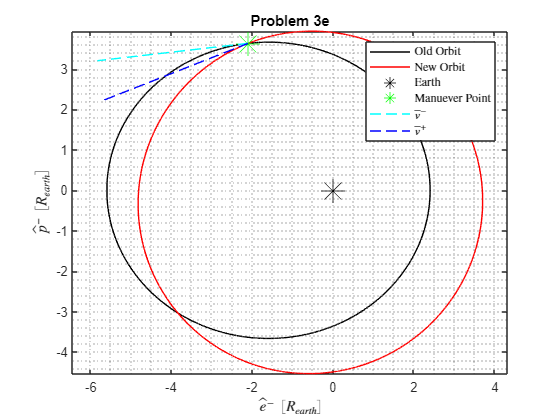

% True anomaly vector
ta_vec          = 0:.01:360;

% Initialize position vectors
r_P_minus_old   = zeros(2,length(ta_vec));  % Old orbit in original perifocal frame 
r_P_plus_new    = r_P_minus_old;            % New orbit in new perifocal frame
r_P_minus_new   = r_P_minus_old;            % New orbit in original perifocal frame

% Rotation matrix from new perifocal frame to original perifocal frame
Pminus_DCM_Pplus= [cosd(deltaAOP), -sind(deltaAOP);...
                   sind(deltaAOP), cosd(deltaAOP)];

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_old               = p_current/(1 + e_current*cosd(ta_vec(i)));

    % Calculate new orbit radii
    r_new               = p_new/(1 + e_new*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R             = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                           sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate old orbit poisition vector from orbit frame to perifocal frame
    r_P_minus_old(:,i)  = P_DCM_R*[r_old;0];

    % Rotate new orbit poisition vector from orbit frame to perifocal frame
    r_P_plus_new(:,i)   = P_DCM_R*[r_new;0];

    % Rotate new orbit position vector from new perifocal frame to original perifocal frame
    r_P_minus_new(:,i)  = Pminus_DCM_Pplus*r_P_plus_new(:,i);

    % Get manuever point
    if ta_vec(i) == ta_manuever
        r_mp    = r_P_minus_old(:,i);
    end
        

end

% Create velocity vectors in orbit frame
v_minus_O         = [v_minus*sind(gamma_minus);v_minus*cosd(gamma_minus)];
v_plus_O          = [v_plus*sind(gamma_plus);v_plus*cosd(gamma_plus)];

% Rotate velocity vectors into original perifocal frame
v_minus_P         = [cosd(ta_manuever), -sind(ta_manuever);...
                     sind(ta_manuever), cosd(ta_manuever)]*v_minus_O;

v_plus_P          = Pminus_DCM_Pplus*[cosd(ta_new), -sind(ta_new);...
                     sind(ta_new), cosd(ta_new)]*v_plus_O;

figure
plot(r_P_minus_old(1,:)/R_earth, r_P_minus_old(2,:)/R_earth,'-k')
hold on
plot(r_P_minus_new(1,:)/R_earth, r_P_minus_new(2,:)/R_earth,'-r')
plot(0, 0,'k*','MarkerSize',18)
plot(r_mp(1)/R_earth, r_mp(2)/R_earth,'g*','MarkerSize',18)
plot([r_mp(1)/R_earth r_mp(1)/R_earth+v_minus_P(1)], [r_mp(2)/R_earth r_mp(2)/R_earth+v_minus_P(2)],'--c')
plot([r_mp(1)/R_earth r_mp(1)/R_earth+v_plus_P(1)], [r_mp(2)/R_earth r_mp(2)/R_earth+v_plus_P(2)],'--b')
grid minor
xlabel('$\hat{e}^- \  [R_{earth}]$', 'Interpreter','latex')
ylabel('$\hat{p}^- \ [R_{earth}]$', 'Interpreter','latex')
axis equal
title('Problem 3e')
legend('Old Orbit','New Orbit','Earth','Manuever Point',...
       '$\bar{v}^-$','$\bar{v}^+$','Interpreter','latex')

**Using the orbit frame vector basis **$\hat{r}, \hat{\theta}, \hat{h}$**, one can determine the difference in the components of the velocity vectors at the manuever point. The velocity vectors  & the difference between them are given below. **


$$\bar{v} = v \sin{\gamma} \ \hat{r} + v \cos{\gamma} \ \hat{\theta} \\

\bar{v}^- = 1.49 \ \hat{r} + 3.45 \ \hat{\theta} \ [km/s] \\

\bar{v}^+ = 0.576 \ \hat{r} + 3.847 \ \hat{\theta} \ [km/s] \\

\Delta \bar{v} = -0.917 \ \hat{r} + 0.397 \ \hat{\theta} \  [km/s]
$$


**The difference in the velocity vectors equals the manuevers that was intended as it should, if they are expressed in the same approrpiate vector basis. The orbit frame vector basis is the same for both velocity vectors at the manuever point, so it was fine to compare them in this frame. The new or original perifocal frames can also be used if both velocity vectors are expressed in the same perifocal frame. The norm of **$\Delta \bar{v}$** above is equal to 1 km/s, which was the desired "deltaV". **